# Atividade 05_05

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Filtro da mediana

Implementar o filtro da mediana na unha. Use laços for à vontade. Pode ser pra uma janela de dimensões hard coded (fixas, que não permitem configurações). Não precisa tratar as bordas. Teste com a imagem salt-and-pepper1.tif e mostre a entrada e saída (in vs. out).

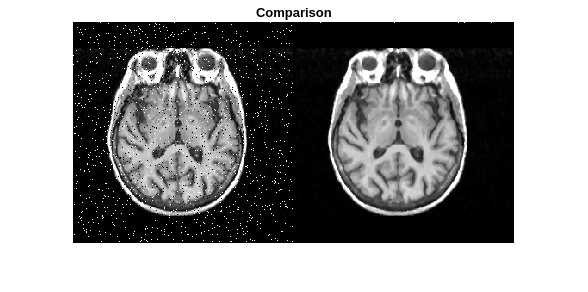

img = imread("salt-and-pepper1.tif");
pImg = img;

[iMax, jMax] = size(img);

for i=2:iMax-1
    for j=2:jMax-1
        box = img(i-1:i+1,j-1:j+1);
        window = reshape(box, 1, []);
        sortedWindow = sort(window);
        pImg(i, j) = sortedWindow(5);
    end
end

figure, imshowpair(img, pImg, "montage")
title("Comparison")